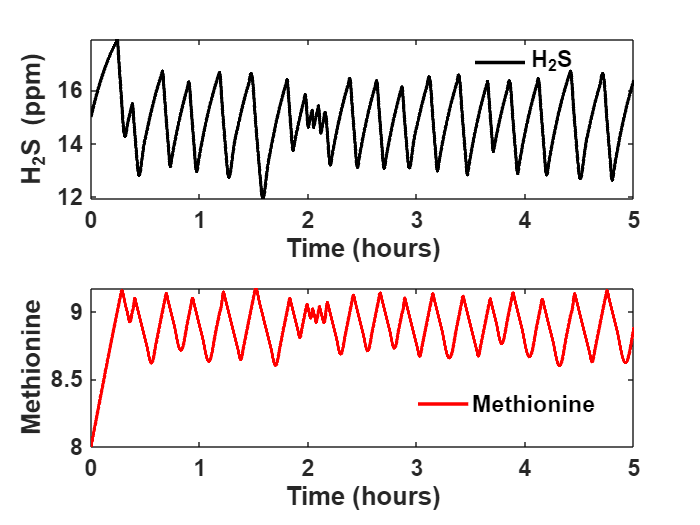

u_max = 0.4;
K_C = 40; 
Y_MetX = 0.1;
K_MetX = 8;
beta1 = 0.02;
alpha1 = 0.001;
beta2 = 0.0020;
alpha2 = 0.0001;
K1 = 9;
K2 = 15;

% initial condition
X0 = 20;
u0 = 0;
C0_Met = 8;
C0_H2S = 15;


% ode solver optimization setting
odeopt = odeset('RelTol',1e-3);

% ode tspan and initial condition
tsapn = 1:3600 *5; % one hour
w0 = [X0, u0, C0_H2S, C0_Met];

% ode solver
[T,W] = ode45(@(t,w) ODEsystem (t,w,u_max,K_MetX,K_C,K1,K2,beta1,alpha1,beta2,alpha2),tsapn, w0, odeopt); 
X = W(:,1);
u = W(:,2);
H2S = W(:,3);
Met = W(:,4);




TimeInMinutes = tsapn/3600;
figure;

subplot(2,1,1);
plot(TimeInMinutes, H2S, 'linewidth', 2, 'color', 'k');
xlabel('Time (hours)','fontsize',14);
ylabel('H_2S (ppm)','fontsize',14);
legend('H_2S','fontsize',14);
set(gca,'FontWeight','bold');
set(gca,'fontsize', 14) 
legend box off;

subplot(2,1,2);
plot(TimeInMinutes, Met, 'linewidth', 2, 'color', 'r'); hold on
xlabel('Time (hours)','fontsize',14);
ylabel('Methionine','fontsize',14);
legend('Methionine','fontsize',14); 
set(gca,'FontWeight','bold');
set(gca,'fontsize', 14) 
legend box off;

subplot(2,1,2)
legend(["Methionine"], "Box", "off", "FontSize", 14)


function dwdt = ODEsystem (t,w,u_max,K_MetX,K_C,K1,K2,beta1,alpha1,beta2,alpha2)
dwdt = zeros (4,1);
dwdt (1) = w(2) * w(1);
w(2) = u_max * w(4) / (K_MetX + w(4)) * ( 1 - w(1)/K_C); 
dwdt (3) = beta1 * (w(4)<K1) -alpha1 * w(3);
dwdt (4) = beta2 * (w(3)>K2) -alpha2 * w(4);
end